## Assignment 3.1

A = [1, -2, 1;
    2, -4, 1;
    1, 2, -2;
    1, -6, 4;
];
b = [-1; -1; 6; -8];
Ab = [A b];
Ab = rref(Ab); % Gaussian Elimination
x = Ab(1:3, 4)

x =      2
     1
    -1


The solution x = [2; 1; -1] is unique. 

## Assignment 3.2

A = [2, -1, 2, -1;
    1, 1, -1, -1;
    1, -1, -1, 1;
];
% nullity of A is 1
P = null(A, 'r')

P =     0.5000
    1.0000
    0.5000
    1.0000


The general solution to the system of equations is  $x=N\left(A\right)=c_1 \cdot {\left(0\ldotp 3162,\;0\ldotp 6325,\;0\ldotp 3162,\;0\ldotp 6325\right)}^T$

## Assignment 3.3

L = [1, 0, 0, 0;
    5, 2, 0, 0;
    1, -1, 3, 0;
    2, 1, 4, -2;
];
b = [1; 5; 13; 22];
my_forward_substitution(L, b)

ans =      1
     0
     4
    -2


## Assignment 3.4

fig='sample_plot.fig';
open(fig)
a = get(gca,'Children');
x = get(a, 'XData'); %extract x-data points
y = get(a, 'YData'); %extract y-data points
A=[sin(x'), cos(x'), ones(size(x'))]; %create the matrix A of basis functions
beta=pinv(A)*y';
hold on
plot(x,beta(1)*sin(x) + beta(2)*cos(x) + beta(3))
str = sprintf('y = %.2fsin(x)+%.2fcos(x)+%.2f', beta)

str = 'y = 1.04sin(x)+1.05cos(x)+0.51'

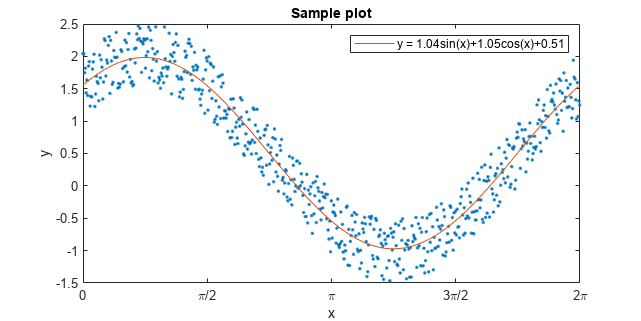

legend({'', str})
set(gcf,'position',[671,661,1000,500])
hold off

The equation of the regression curve is $\hat{y} \left(x\right)=1\ldotp 04\sin \left(x\right)+1\ldotp 05\cos \left(x\right)+0\ldotp 51$

## Assignment 3.5

x=[0 1 2 3];
y=[1 4 3 6];
xq=1.2;
linear_interpol(x, y, xq)

ans = 3.8000

## Assignment 3.6

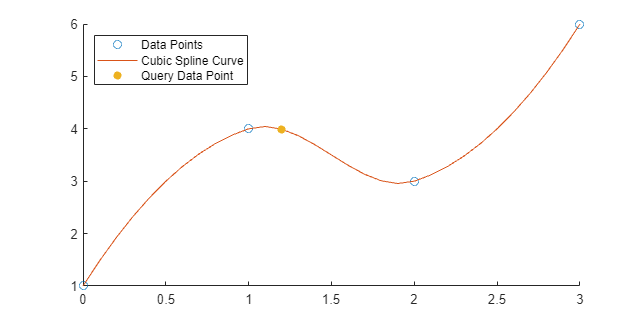

x=[0 1 2 3];
y=[1 4 3 6];
xq=1.2;
scatter(x,y)
hold on
plot(0:0.1:3, interp1(x, y, 0:0.1:3, 'cubic'))
scatter(xq, interp1(x, y, xq, 'cubic'), 'filled')
legend({'Data Points', 'Cubic Spline Curve', 'Query Data Point'}, 'Location','northwest')
hold off

## Assignment 3.7

x=[0 1 2 3];
y=[1 4 3 6];
xq=1.2; 
Lagrange_interpol(x, y, xq)

ans = 3.8640

## Assignment 3.8

format long
pi_approx(21)

ans =    3.141592653589794


## Assignment 3.9

clearvars
syms f(x)
f(x)=@(x)1/(x-2)+exp(x)

$$f(x) = {\mathrm{e}}^{x}+\frac{1}{x-2}$$

guess_int=[1.5 1.9];
L=1;
while abs(L) > 0.001
    root = (guess_int(1)+guess_int(2))/2;
    L = f(root);
    if f(guess_int(1))*f(root) < 0
        guess_int=[guess_int(1) root];
    else
        guess_int=[root guess_int(2)];
    end
end
fprintf("One of root: %f", root)

One of root: 1.841406

fprintf("Loss: %f", abs(L))

Loss: 0.000020

If choose the guess interval [1.9,2.1], it will never get the root of the equation. 

## Assignment 3.10

To find the maximum value of function$x^3 -{\textrm{e}}^x$ is to find the root of its derivative. 

clearvars
syms f(x)
f(x)=@(x)x^3-exp(x)

$$f(x) = x^{3}-{\mathrm{e}}^{x}$$

g(x)=diff(f(x))

$$g(x) = 3\,x^{2}-{\mathrm{e}}^{x}$$

dg(x)=diff(g(x))

$$dg(x) = 6\,x-{\mathrm{e}}^{x}$$


root = 4;
while abs(g(root)) > 0.001
    root = root-g(root)/dg(root);
end

fprintf("Root: %f", root)

Root: 3.733084

fprintf("Maximum: %f", f(root))

Maximum: 10.216101

## Assignment 3 Function Define

function x = my_forward_substitution(L, b)      % 3.3
n = length(b);
x(1, 1) = b(1) / L(1, 1);
for i = 2:n
    x(i, 1) = (b(i)-L(i, 1:i-1)*x(1:i-1, 1))./L(i, i);
end
end

function [yq]=linear_interpol(x,y,xq)           % 3.5
% use for to find i
for k = 1:length(x)
    if xq < k
    i = k;
    break
    end
end
yq = y(i) + (xq-x(i))*(y(i+1)-y(i))/(x(i+1)-x(i));
end

function yq=Lagrange_interpol(x,y, xq)          % 3.7
n=size(x,2);
L=ones(n,size(xq,2));
for i=1:n
  for j=1:n
     if (i~=j)
        L(i,:)=L(i,:).*(xq-x(j))/(x(i)-x(j));
     end
  end
end
yq=0;
for i=1:n
  yq=yq+y(i)*L(i,:);
end
end

function out=pi_approx(k)                       % 3.8
x = 1/2;
out=0;
for i=0:k
    out = out + factorial(2 * i) * x.^(2 * i + 1) / ((4 ^ i) * ((factorial(i)) ^ 2) * (2 * i + 1));
end
out=out*6;
end

